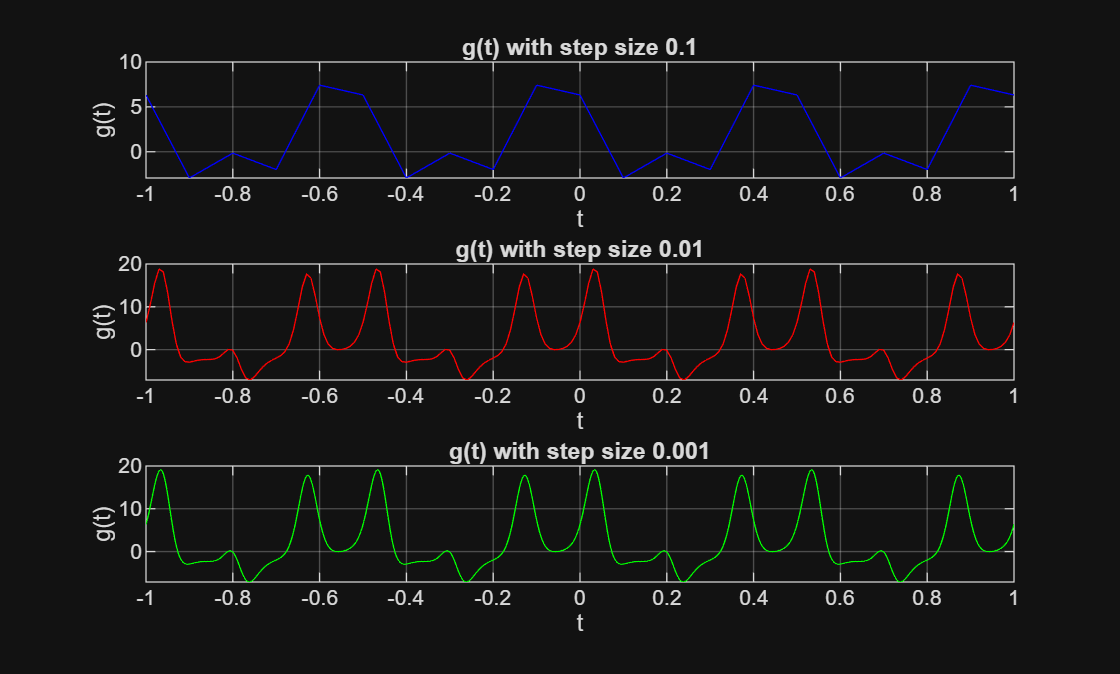

% 1.
% Define the function g(t)
g = @(t) 3*pi*sin(8*pi*t + 1.3).*cos(4*pi*t - 0.8).*exp(sin(12*pi*t));

% Define the time ranges for different step sizes
t1 = -1:0.1:1;
t2 = -1:0.01:1;
t3 = -1:0.001:1;

% Create a figure
figure;

% Plot for step size 0.1
subplot(3, 1, 1);
plot(t1, g(t1), 'b');
title('g(t) with step size 0.1');
xlabel('t');
ylabel('g(t)');
grid on;

% Plot for step size 0.01
subplot(3, 1, 2);
plot(t2, g(t2), 'r');
title('g(t) with step size 0.01');
xlabel('t');
ylabel('g(t)');
grid on;

% Plot for step size 0.001
subplot(3, 1, 3);
plot(t3, g(t3), 'g');
title('g(t) with step size 0.001');
xlabel('t');
ylabel('g(t)');
grid on;


% Calculate the period of the signal
% The period can be determined from the sine and cosine components
T = 0.5;
disp(['The period of the signal is: 0.5 seconds']);

The period of the signal is: 0.5 seconds


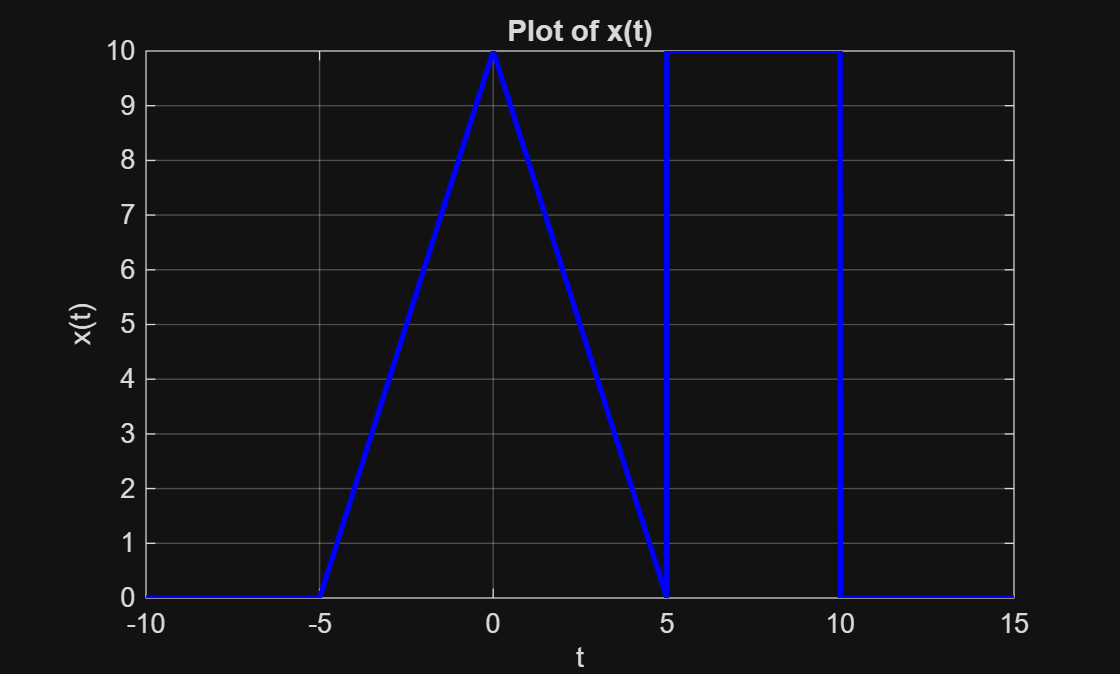

% 2.
% Define the piecewise function x(t)
x = @(t) (-2*abs(t) + 10) .* (t >= -5 & t < 5) + ...
          10 * (t >= 5 & t < 10) + ...
          0 * (t < -5 | t >= 10);

% Define the time vector for plotting
t = -10:0.01:15; % Fine resolution for smooth plotting

% Create the first figure for x(t)
figure;
plot(t, x(t), 'b', 'LineWidth', 2);
title('Plot of x(t)');
xlabel('t');
ylabel('x(t)');
grid on;

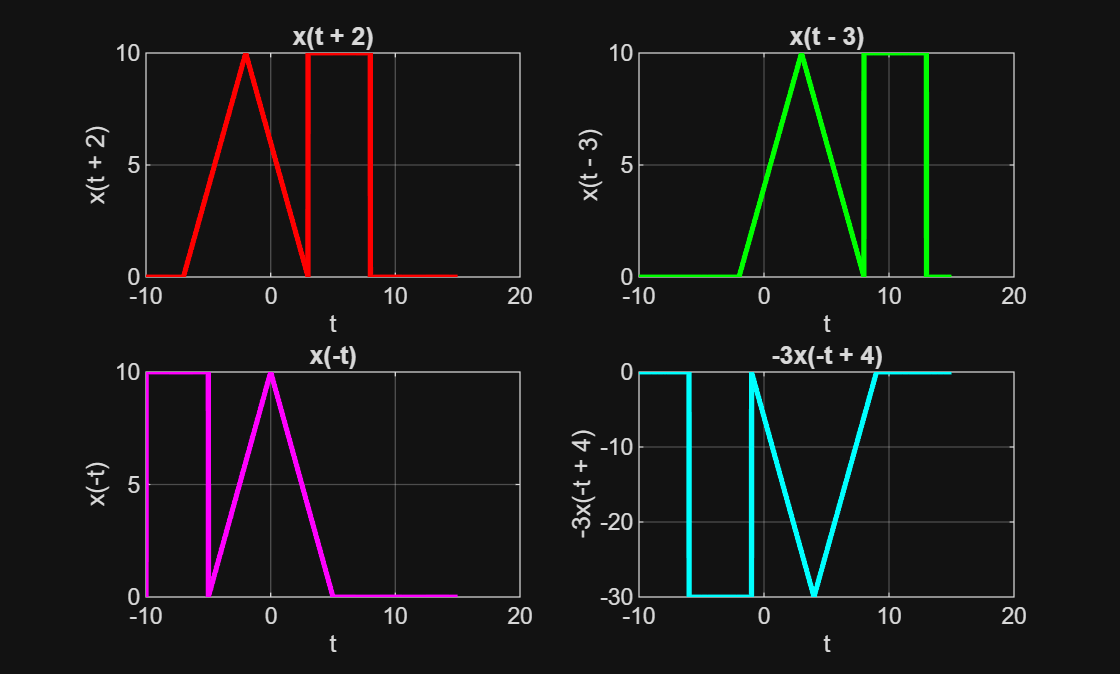


% Create a new figure for the transformed signals
figure;

% Define the transformed signals
subplot(2, 2, 1);
plot(t, x(t + 2), 'r', 'LineWidth', 2);
title('x(t + 2)');
xlabel('t');
ylabel('x(t + 2)');
grid on;

subplot(2, 2, 2);
plot(t, x(t - 3), 'g', 'LineWidth', 2);
title('x(t - 3)');
xlabel('t');
ylabel('x(t - 3)');
grid on;

subplot(2, 2, 3);
plot(t, x(-t), 'm', 'LineWidth', 2);
title('x(-t)');
xlabel('t');
ylabel('x(-t)');
grid on;

subplot(2, 2, 4);
plot(t, -3*x(-t + 4), 'c', 'LineWidth', 2);
title('-3x(-t + 4)');
xlabel('t');
ylabel('-3x(-t + 4)');
grid on;

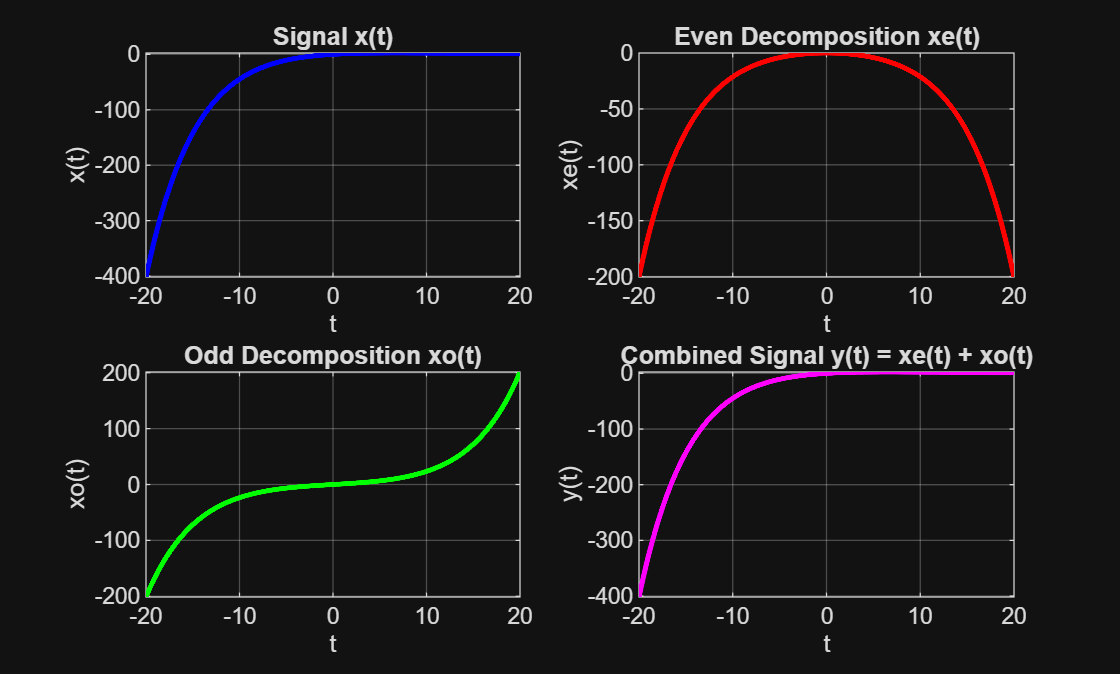

% 3.
% Define the time vector
t = -20:0.01:20; % Time range from -20 to 20

% Define the signal x(t)
x = @(t) t .* exp(-0.15 * t); % x(t) = te^(-0.15t)

% Calculate the signal x(t)
xt = x(t);

% Plot x(t)
figure;
subplot(2, 2, 1);
plot(t, xt, 'b', 'LineWidth', 2);
title('Signal x(t)');
xlabel('t');
ylabel('x(t)');
grid on;

% Calculate even and odd decompositions
xe = @(t) (x(t) + x(-t)) / 2; % Even part
xo = @(t) (x(t) - x(-t)) / 2; % Odd part

% Calculate the even and odd signals
xe_t = xe(t);
xo_t = xo(t);

% Plot the even decomposition xe(t)
subplot(2, 2, 2);
plot(t, xe_t, 'r', 'LineWidth', 2);
title('Even Decomposition xe(t)');
xlabel('t');
ylabel('xe(t)');
grid on;

% Plot the odd decomposition xo(t)
subplot(2, 2, 3);
plot(t, xo_t, 'g', 'LineWidth', 2);
title('Odd Decomposition xo(t)');
xlabel('t');
ylabel('xo(t)');
grid on;

% Calculate the combined signal y(t) = xe(t) + xo(t)
y_t = xe_t + xo_t;

% Plot the combined signal y(t)
subplot(2, 2, 4);
plot(t, y_t, 'm', 'LineWidth', 2);
title('Combined Signal y(t) = xe(t) + xo(t)');
xlabel('t');
ylabel('y(t)');
grid on;

% 4.
% Define the signal g(t)
g = @(t) 3*pi*sin(8*pi*t + 1.3).*cos(4*pi*t - 0.8).*exp(sin(12*pi*t));

% Define the time interval
a = 0.25;
b = 0.75;

% Calculate the energy of the signal
energy = integral(@(t) abs(g(t)).^2, a, b);

% Calculate the power of the signal
power = energy / (b - a);

% Display the results
disp(['Energy of the signal in the interval [0.25, 0.75]: ', num2str(energy)]);

Energy of the signal in the interval [0.25, 0.75]: 27.3775


disp(['Power of the signal in the interval [0.25, 0.75]: ', num2str(power)]);

Power of the signal in the interval [0.25, 0.75]: 54.755


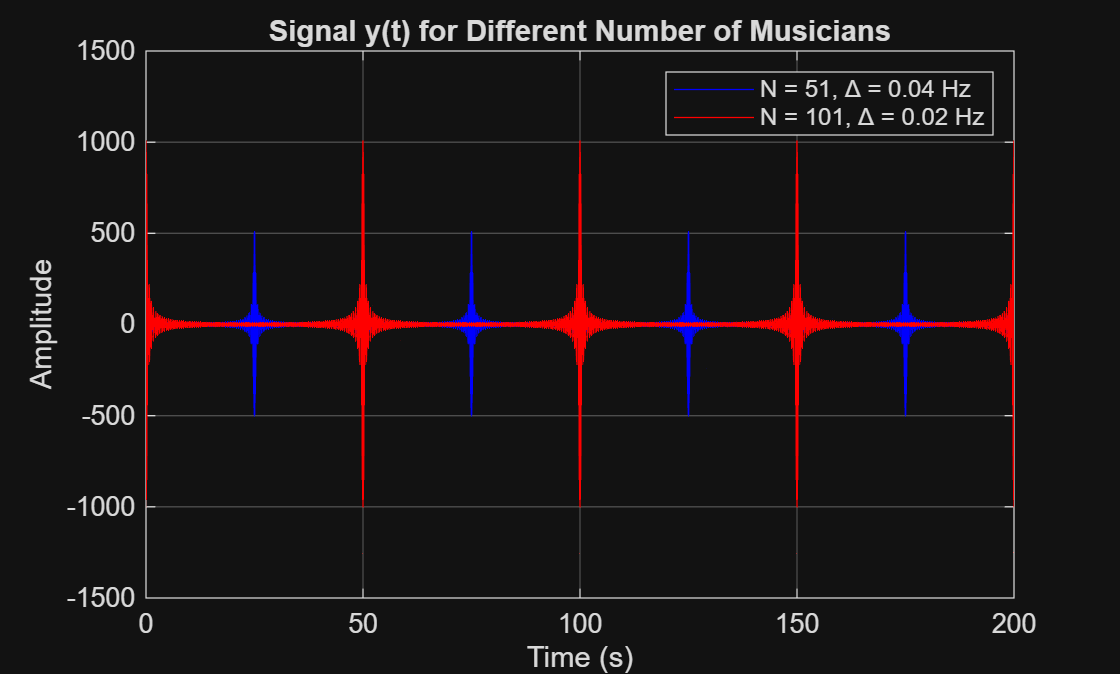

% 5.
% Define the time vector
t = 0:0.001:200; % Time from 0 to 200 seconds with a sampling rate of 1000 Hz

% Case 1: N = 51, Δ = 0.04 Hz
N1 = 51;
delta1 = 0.04;
f1 = 159 + (0:N1-1) * delta1; % Frequencies from 159 Hz to 161 Hz
y1 = zeros(size(t)); % Initialize y(t)

% Generate the signal y(t) for N = 51
for i = 1:N1
    y1 = y1 + 10 * cos(2 * pi * f1(i) * t);
end

% Case 2: N = 101, Δ = 0.02 Hz
N2 = 101;
delta2 = 0.02;
f2 = 159 + (0:N2-1) * delta2; % Frequencies from 159 Hz to 161 Hz
y2 = zeros(size(t)); % Initialize y(t)

% Generate the signal y(t) for N = 101
for i = 1:N2
    y2 = y2 + 10 * cos(2 * pi * f2(i) * t);
end

% Plotting the results
figure;
plot(t, y1, 'b', 'DisplayName', 'N = 51, Δ = 0.04 Hz');
hold on;
plot(t, y2, 'r', 'DisplayName', 'N = 101, Δ = 0.02 Hz');
title('Signal y(t) for Different Number of Musicians');
xlabel('Time (s)');
ylabel('Amplitude');
legend show;
grid on;
hold off;